% =========================================================================
%  System Identification Project - Part 3: Statistical Black-Box Identification
%  Fully Validated, Clean, and Optimized Version (ARX and FIR Estimation)
% =========================================================================

clear; clc; close all;

% Step 0: Reconstruction of Continuous-Time Transfer Function (sys_speed)
J1 = 5e-5; B1 = 1e-2; r1 = 2e-2; Kt = 3e-2; K = 2e+4; B = 20; J2 = 2e-5; B2 = 2e-2; r2 = 2e-2;
num_speed = Kt*r1 * [J2, (B2 + r2^2*B), r2^2*K];
den_speed = [J1*J2, (J1*B2 + B1*J2 + r2^2*J1*B + r1^2*J2*B), ...
             (B1*B2 + r2^2*J1*K + r1^2*J2*K + r1^2*B2*B + r2^2*B1*B), ...
             (r1^2*B2*K + r2^2*B1*K)];
sys_speed = tf(num_speed, den_speed);

%% 1. Data Generation (Wideband PRBS Input)
Ts = 0.001; 
T_final = 5; 
t = (0:Ts:T_final)';

% Generate Pseudo-Random Binary Sequence (PRBS) input to excite all system frequencies
u_ident = idinput(length(t), 'prbs', [0 1]); 


% Simulate the velocity response of the continuous plant to the PRBS input
y_ident = lsim(sys_speed, u_ident, t);

% Add Gaussian White Noise to simulate real sensor measurement distortions
noise = 0.0001 * randn(size(y_ident));
y_ident = y_ident + noise;

%% 2. Data Partitioning (50/50 Train and Test Splitting)
N = length(y_ident);
half_N = floor(N/2);

% Estimation dataset (First half used for model training)
u_est = u_ident(1:half_N); y_est = y_ident(1:half_N);
data_est = iddata(y_est, u_est, Ts);

% Validation dataset (Second half used for testing unseen dynamics)
u_val = u_ident(half_N+1:end); y_val = y_ident(half_N+1:end);
data_val = iddata(y_val, u_val, Ts);

fprintf('Total Samples Generated: %d | Estimation Set: %d | Validation Set: %d\n', N, half_N, length(u_val));

Total Samples Generated: 5001 | Estimation Set: 2500 | Validation Set: 2501


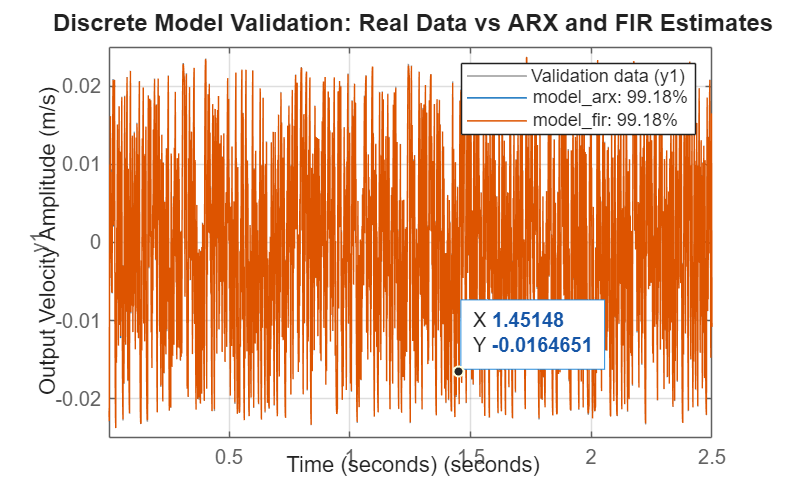


%% 3. Parametric Estimation (ARX & FIR Structures)
% Automatic order estimation for ARX model based on Minimum Description Length (MDL) criterion
V = arxstruc(data_est, data_val, struc(1:10, 1:10, 1:10));
best_order = selstruc(V, 'mdl');

% Build the optimal parametric ARX model
model_arx = arx(data_est, best_order);

% Build the Finite Impulse Response (FIR) model (na=0 eliminates output feedback)
model_fir = arx(data_est, [0, 50, 1]);

%% 4. Model Validation & Graphical Analysis

% Plot 1: Model Validation Output Tracking (Validation Fit Percentage)
figure('Name', 'Model Validation Compare', 'Position', [100, 100, 800, 500]);
compare(data_val, model_arx, model_fir);
title('Discrete Model Validation: Real Data vs ARX and FIR Estimates', 'FontSize', 12);
xlabel('Time (seconds)', 'FontSize', 11);
ylabel('Output Velocity Amplitude (m/s)', 'FontSize', 11);
grid on;

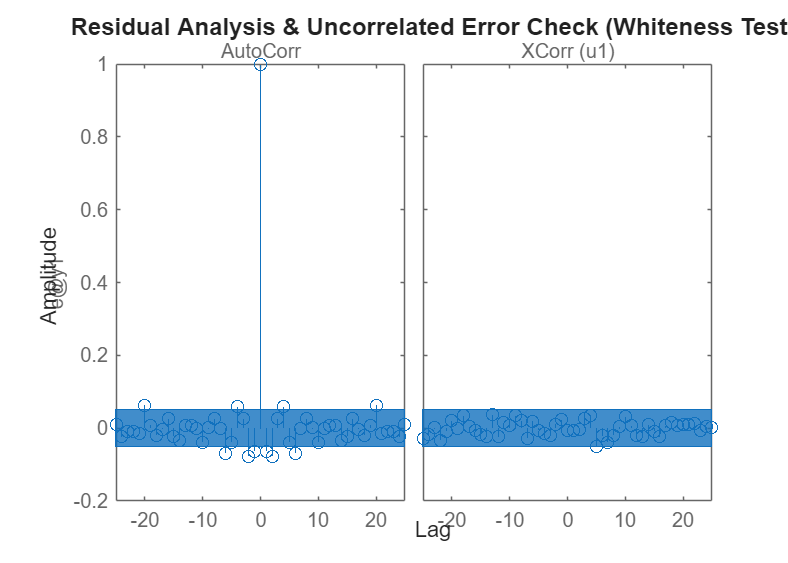


% Plot 2: Residual Analysis and Whiteness Autocorrelation Test for ARX Model
figure('Name', 'Residual Analysis', 'Position', [200, 150, 700, 500]);
resid(data_val, model_arx);
title('Residual Analysis & Uncorrelated Error Check (Whiteness Test)', 'FontSize', 12);

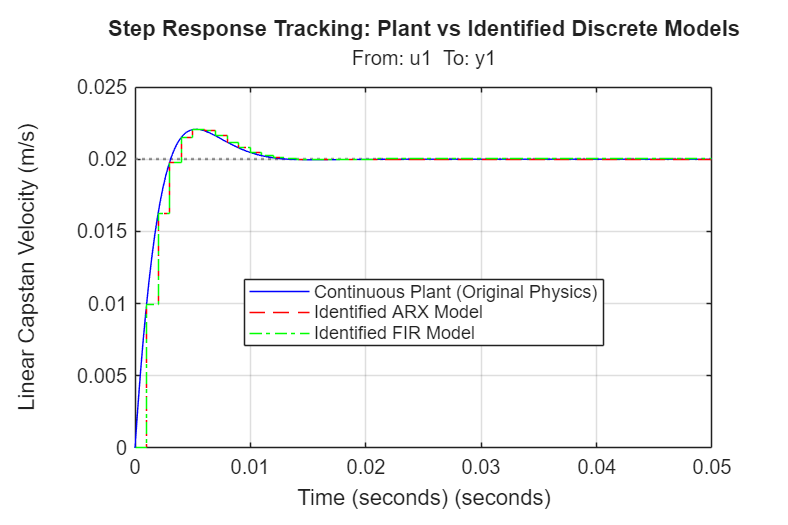


% Plot 3: Step Response Comparison (Continuous Plant vs Identified Models)
figure('Name', 'Step Response Comparison', 'Position', [300, 200, 750, 500]);
step(sys_speed, 'b', model_arx, 'r--', model_fir, 'g-.', 0.05);
legend('Continuous Plant (Original Physics)', 'Identified ARX Model', 'Identified FIR Model', 'Location', 'best');
title('Step Response Tracking: Plant vs Identified Discrete Models', 'FontSize', 11);
xlabel('Time (seconds)', 'FontSize', 11);
ylabel('Linear Capstan Velocity (m/s)', 'FontSize', 11);
grid on;

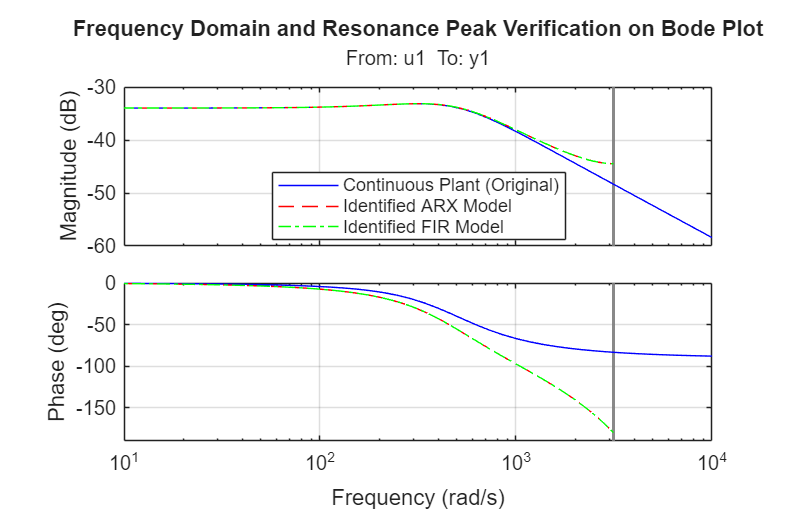


% Plot 4: Frequency Domain Comparison (Bode Plot for Elastic Tape Resonance Check)
figure('Name', 'Bode Plot Comparison', 'Position', [400, 250, 750, 500]);
bode(sys_speed, 'b', model_arx, 'r--', model_fir, 'g-.');
legend('Continuous Plant (Original)', 'Identified ARX Model', 'Identified FIR Model', 'Location', 'best');
title('Frequency Domain and Resonance Peak Verification on Bode Plot', 'FontSize', 11);
grid on;

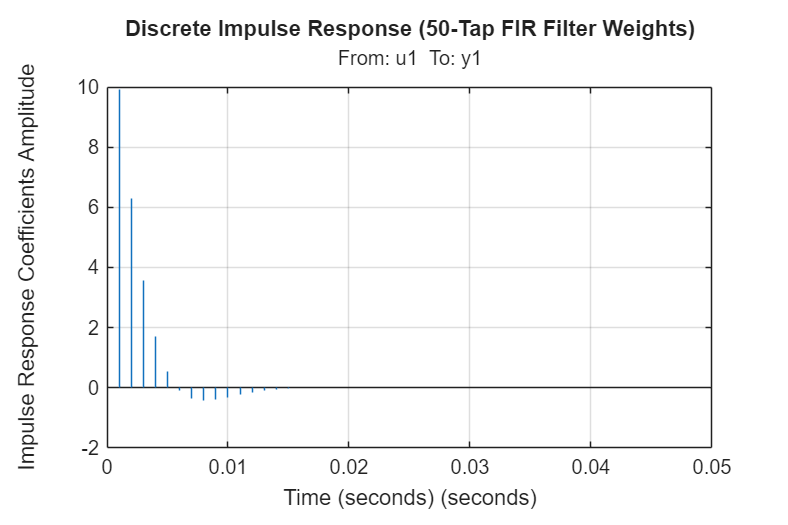


% Plot 5: FIR Model Impulse Coefficients (Filter Taps Output)
figure('Name', 'FIR Coefficients Impulse', 'Position', [500, 300, 600, 400]);
impulse(model_fir, 0.05);
title('Discrete Impulse Response (50-Tap FIR Filter Weights)', 'FontSize', 11);
xlabel('Time (seconds)', 'FontSize', 11);
ylabel('Impulse Response Coefficients Amplitude', 'FontSize', 11);
grid on;


%% 5. Numerical Parameters Summary in MATLAB Command Window
fprintf('\n======================================================\n');

fprintf('     Mathematical Matrix Structure for ARX Model     \n');

     Mathematical Matrix Structure for ARX Model     


fprintf('======================================================\n');

present(model_arx);


model_arx =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                                                                                                                                                                     
  A(z) = 1 - 0.05811 (+/- 0.0199) z^-1 - 0.03965 (+/- 0.01956) z^-2 - 0.003301 (+/- 0.01916) z^-3 + 0.01866 (+/- 0.01863) z^-4 - 0.03397 (+/- 0.01776) z^-5 - 0.05909 (+/- 0.0173) z^-6 - 0.003797 (+/- 0.01719) z^-7 + 0.06447 (+/- 0.009302) z^-8                     
                                                                                                                                                                                                                                                                        
  B(z) = 0.009932 (+/- 1.998e-06) z^-1 + 0.005729 (+/- 0.0001977) z^-2 + 0.002807 (+/- 0.0002216) z^-3 + 0.00121 (+/- 0.0002163) z^-4 + 0.0004728 (+/- 0.0001986) z^-5 - 0.0004122 (+/- 0.000167


fprintf('\n======================================================\n');

fprintf('          Polynomial Coefficients for FIR Model       \n');

          Polynomial Coefficients for FIR Model       


fprintf('======================================================\n');

[~, B_coeff] = polydata(model_fir);
disp(B_coeff);

         0    0.0099    0.0063    0.0036    0.0017    0.0005   -0.0001   -0.0004   -0.0004   -0.0004   -0.0003   -0.0002   -0.0001   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

